**Question (4.a):**

Design a causal, stable magnitude inverse of the system. Draw magnitude, phase and group delay response of the inverse sytem.

**Answer (4.a):**

$H\left(z\right)$ (stable & causal) is a non-minimum-phase system (doesn't have all poles and zeros inside unit circle), so its rational inverse $1/H\left(z\right)$ is not stable & causal. But, any system $H\left(z\right)$ can be decomposed into minimum-phase $H_{\min } \left(z\right)$ and all-pass $H_{\textrm{ap}} \left(z\right)$ systems, as follows:


$$H\left(z\right)\;=\;H_{\min } \left(z\right){\;H}_{\textrm{ap}} \left(z\right)$$


where $H_{\min } \left(z\right)$ has all its poles and zeros inside the unit-circle, that is, it and its inverse ($1/H_{\min } \left(z\right)$) are stable & causal; while $H_{\textrm{ap}} \left(z\right)$ has constant (unity) magnitude. In terms of magnitude, $H_{\textrm{ap}} \left(z\right)$ does not have any contribution, hence the magnitude distortion in $H\left(z\right)$ comes from $H_{\min } \left(z\right)$. 

So, to compensate for this magnitude distortion, we may use the system given by $1/H_{\min } \left(z\right)$ — which will be a casual and stable magnitude inverse of $H\left(z\right)$. We'll call the inverse system $H_{\textrm{inv}} \left(z\right)$, given as,


$$H_{\mathrm{inv}} \left(z\right)\;=\;\frac{1}{H_{\min } \left(z\right)}$$


First, we decompose $H\left(z\right)$ into $H_{\min } \left(z\right)$ and $H_{\textrm{ap}} \left(z\right)$.

$H\left(z\right)$ has two zeros outside the unit-circle (at $a_2 =1\ldotp 25e^{j\;0\ldotp 8\pi }$ and $a_2^{\ast } =1\ldotp 25e^{-j\;0\ldotp 8\pi }$). So, first place a zero and a pole at conjugate-reciprocal positions ($0\ldotp 8e^{\mp j\;0\ldotp 8\pi }$) of these zeros. So, we have,


$$H\left(z\right)\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}$$


This does not change overall $H\left(z\right)$ as the pole & zero cancel out to give original $H\left(z\right)$. From this expression, we can extract an all-pass system, of the form with $M_c =1$ complex-conjugate pole-pair & respective reciprocal zero-pair,


$$H_{\mathrm{ap}} \left(z\right)\;=\;\frac{\left(z^{-1} -{e_k }^{\ast } \right)\left(z^{-1} -e_k \right)}{\left(1-e_k {\;z}^{-1} \right)\left(1-e_k^{\ast } {\;z}^{-1} \right)}$$


obtained by keeipng the new zeros (placed inside unit-circle) in $H_{\min } \left(z\right)$ and putting the outside zeros along with new inside poles into the $H_{\textrm{ap}} \left(z\right)$ part. 

The decomposition proceeds as follows:

            
$$H\left(z\right)\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}$$


            
$$\begin{array}{l}
H\left(z\right)\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{{\left(1\ldotp 25\right)}^2 \left(0\ldotp 8z-e^{j\;0\ldotp 8\pi } \right)\left(0\ldotp 8z-e^{-j\;0\ldotp 8\pi } \right)}{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\times \;\frac{z^{-2} \left(e^{-j\;0\ldotp 8\pi } \right)\left(e^{j\;0\ldotp 8\pi } \right)}{z^{-2} }
\end{array}$$


            
$$H\left(z\right)\;=\;{\left(1\ldotp 25\right)}^2 \frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{\left(0\ldotp 8e^{-j\;0\ldotp 8\pi } -z^{-1} \right)\left(0\ldotp 8e^{j\;0\ldotp 8\pi } -z^{-1} \right)}{\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)}$$


            
$$\begin{array}{l}
H\left(z\right)\;=\;{\left(1\ldotp 25\right)}^2 \left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\times \frac{\left(z^{-1} -0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z^{-1} -0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)}
\end{array}$$


And so, the all-pass and minimum-phase parts of the system are respectively,


$$\begin{array}{l}
{\;\;H}_{\textrm{ap}} \left(z\right)\;=\;\frac{\left(z^{-1} -0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z^{-1} -0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)}\\
\\
H_{\min } \left(z\right)\;=\;{\left(1\ldotp 25\right)}^2 \left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)
\end{array}$$


Finally, the magnitude inverse system of $H\left(z\right)$ is given by,


$$\begin{array}{l}
H_{\textrm{inv}} \left(z\right)\;=\;\frac{1}{H_{\min } \left(z\right)}\;=\;\frac{1}{{\left(1\ldotp 25\right)}^2 \left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{z^4 }{{\left(1\ldotp 25\right)}^2 \left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}
\end{array}$$


which is causal & stable since all its poles and zeros lie inside unit circle.

The code, along with the results (inline), to compute & plot various responses from $H_{\textrm{inv}} \left(z\right)$ expression above, starts below.

% <task> plot magnitude and phase response of inverse system Hinv(z)

% define z-domain expression (symbolically)
syms z;
a1 = 0.9*exp(1i*0.6*pi);
a2 = 0.8*exp(1i*0.8*pi);
Hinvz_N = z^4;                                                  % numerator of Hinv(z)
Hinvz_D = (1.25^2)*(z-a1)*(z-conj(a1))*(z-conj(a2))*(z-a2);     % denominator of Hinv(z)
Hinvz = Hinvz_N/Hinvz_D;

% display Hinv(z) expression
disp('Hinv(z) = '); disp(vpa(Hinvz, 4))

Hinv(z) = 


$$\frac{z^{4}}{\left(1.562\,z+0.4346-1.337\,\mathrm{i}\right)\,\left(z+0.2781+0.856\,\mathrm{i}\right)\,\left(z+0.6472-0.4702\,\mathrm{i}\right)\,\left(z+0.6472+0.4702\,\mathrm{i}\right)}$$

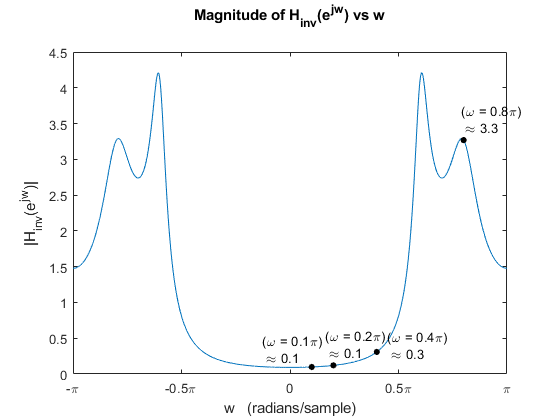


% obtain frequency response Hinv(w) expression from Hinv(z) by substituting z = e^(jw)
syms w_;
Hinvw = subs(Hinvz, {z}, {exp(1i*w_)});

% compute frequency response Hinv(w) for w = [-pi, pi]
dw = 0.001;
w = -pi:dw:pi;
Hinvw = subs(Hinvw, {w_}, {w});
Hinvw = double(Hinvw);

% obtain magnitude and phase of Hinv(w)
Hinvw_mag = abs(Hinvw);
Hinvw_arg = phase(Hinvw);           % unwrapped phase (in radians)
Hinvw_ARG = angle(Hinvw);           % wrapped phase (in radians)

% frequencies to be noted/marked on the response plots
wvals = [0.1, 0.2, 0.4, 0.8]*pi;

% plot magnitude of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_mag);
xlabel('w   (radians/sample)'); 
ylabel('|H_{inv}(e^{jw})|');
title({'Magnitude of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1);
markOnPlot(wvals, w, Hinvw_mag, dw, ...
    [-0.23 -0.04 0.045 -0.01]*pi, [0.25 0.3 0.1 0.3], {'(\omega = ', '\pi)', ''}, pi);

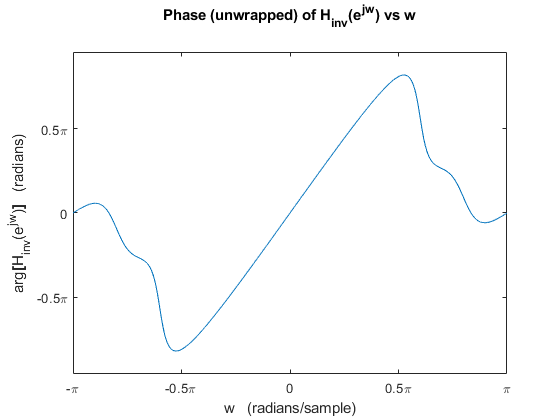


% plot phase (unwrapped) of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_arg);
xlabel('w   (radians/sample)'); 
ylabel('arg{\bf[}H_{inv}(e^{jw}){\bf]}   (radians)');
title({'Phase (unwrapped) of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

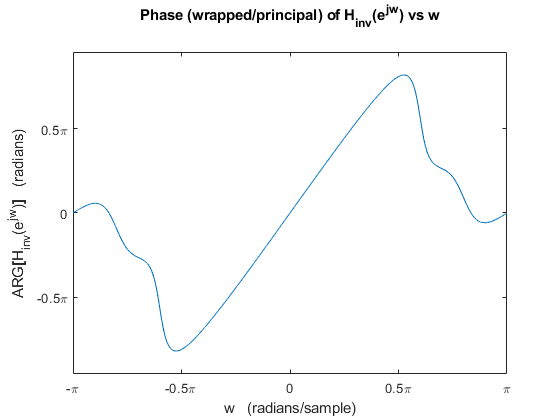


% plot phase (wrapped/principal) of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_ARG);
xlabel('w   (radians/sample)'); 
ylabel('ARG{\bf[}H_{inv}(e^{jw}){\bf]}   (radians)');
title({'Phase (wrapped/principal) of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

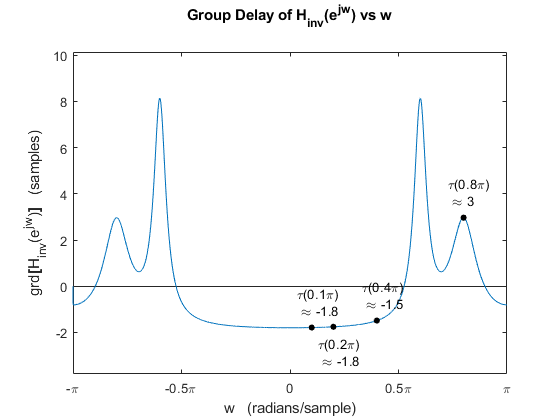


% <task> plot group-delay of inverse system Hinv(z)

dw = (w(end)-w(1))/(length(w)-1);           % compute the w-step-size 'dw' used in w-array

% obtain group-delay of Hinv(w)
Hinvw_grd = -([Hinvw_arg 0]-[0 Hinvw_arg])/dw;
Hinvw_grd = Hinvw_grd(1:(length(Hinvw_grd)-1));

% plot group-delay of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_grd);
xlabel('w   (radians/sample)'); ylabel('grd{\bf[}H_{inv}(e^{jw}){\bf]}   (samples)');
title({'Group Delay of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1); ylim([min(Hinvw_grd)-2 max(Hinvw_grd)+2]);
markOnPlot(wvals, w, Hinvw_grd, dw, -0.07*pi, [1 -1 1 1]*1.1, {'\tau(', '\pi)', ''}, pi);


% <task> plot pole-zero map of inverse system Hinv(z)

% extract CCDE coefficients (b's and a's) from Hinv(z) expression
[N, D] = numden(Hinvz);
b = coeffs(N, 'All');   a = coeffs(D, 'All');
b = double(b./a(1));    a = double(a./a(1));
disp('b ='); disp(b);   disp('a ='); disp(a);

b =
    0.6400         0         0         0         0

a =
    1.0000    1.8507    2.1700    1.4045    0.5184



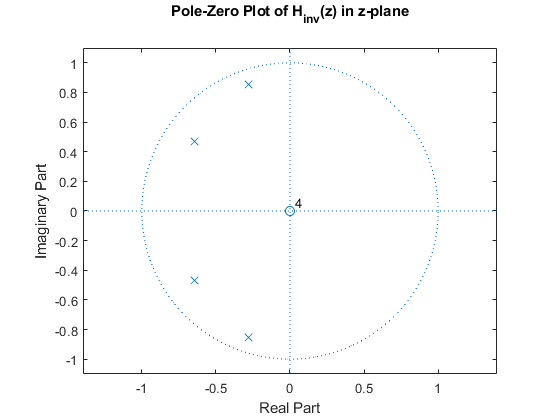


% plot the pole-zero map of Hinv(z) using extracted b's and a's
figure;
zplane(b, a);
title({'Pole-Zero Plot of H_{inv}(z) in z-plane';''});

All poles (and zeros) of $H_{\textrm{inv}} \left(z\right)$ lie within the unit-cricle. A possible ROC is that extending outward from outermost pole, $|z|>0\ldotp 9$. If ROC $|z|>0\ldotp 9$ is selected, then $H_{\textrm{inv}} \left(z\right)$ is stable as well as causal.

**Question (4.b):**

Pass all $y\left\lbrack n\right\rbrack$ obtained in the previous part through the the inverse system.

What is the maximum magnitude of the output of the inverse system? Can you explain the different maximum magnitudes of the output signals corresponding to different $\omega_c$?

Do you think you have gotten exactly the same $x\left\lbrack n\right\rbrack$ at the output of the inverse system? Why or why not?

**Answer (4.b):**

Let $g\left\lbrack n\right\rbrack$ be the output of the magnitude inverse system. The overall system block diagram will be,

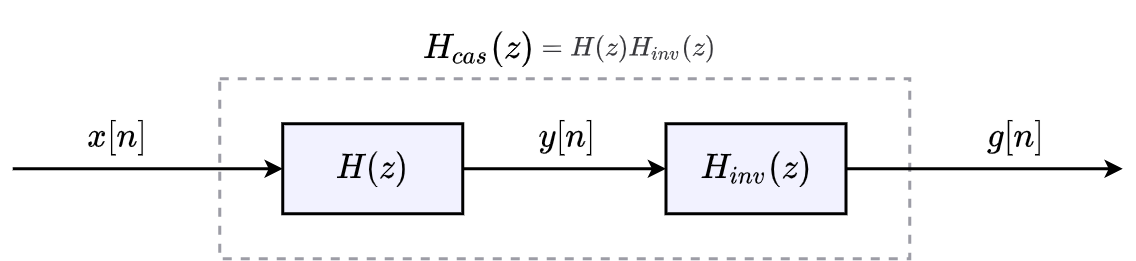

The code, along with the results, to pass $y\left\lbrack n\right\rbrack$ for each $\omega_c$ through $H_{\textrm{inv}} \left(z\right)$, starts below.

***Note:***  The maximum magnitudes have been marked in the output spectrum Figures.

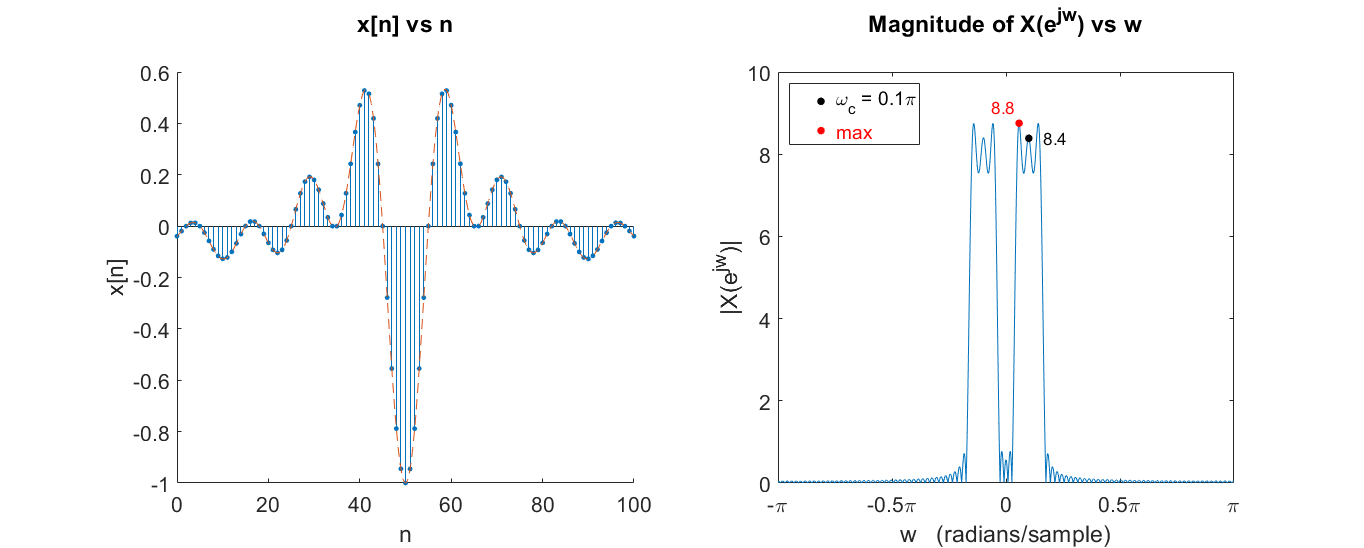

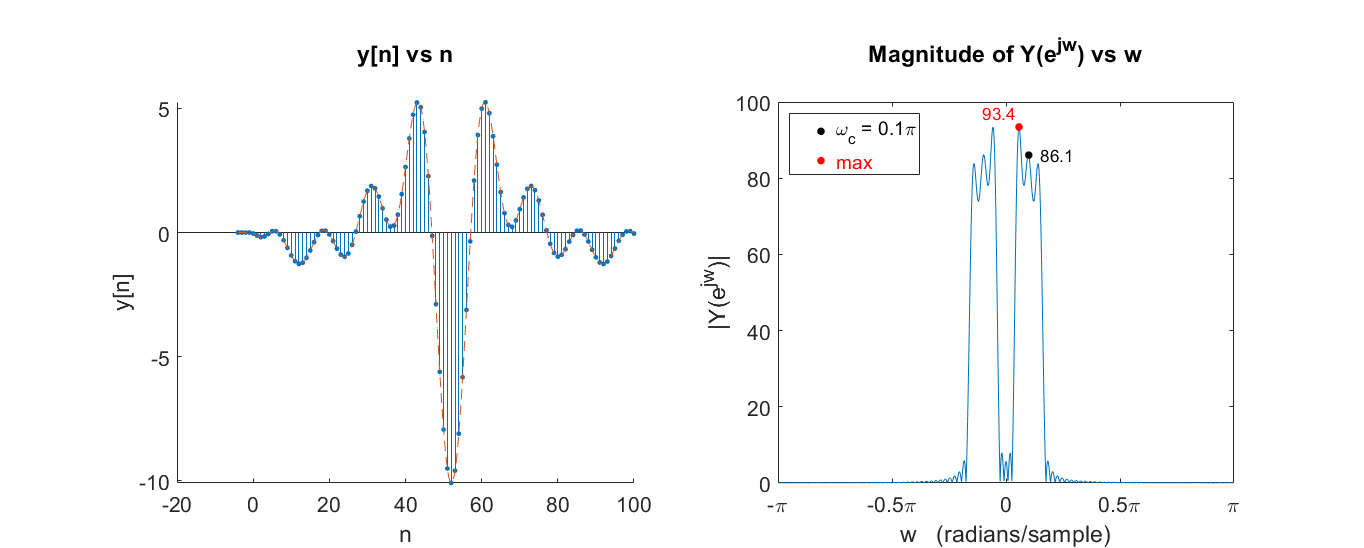

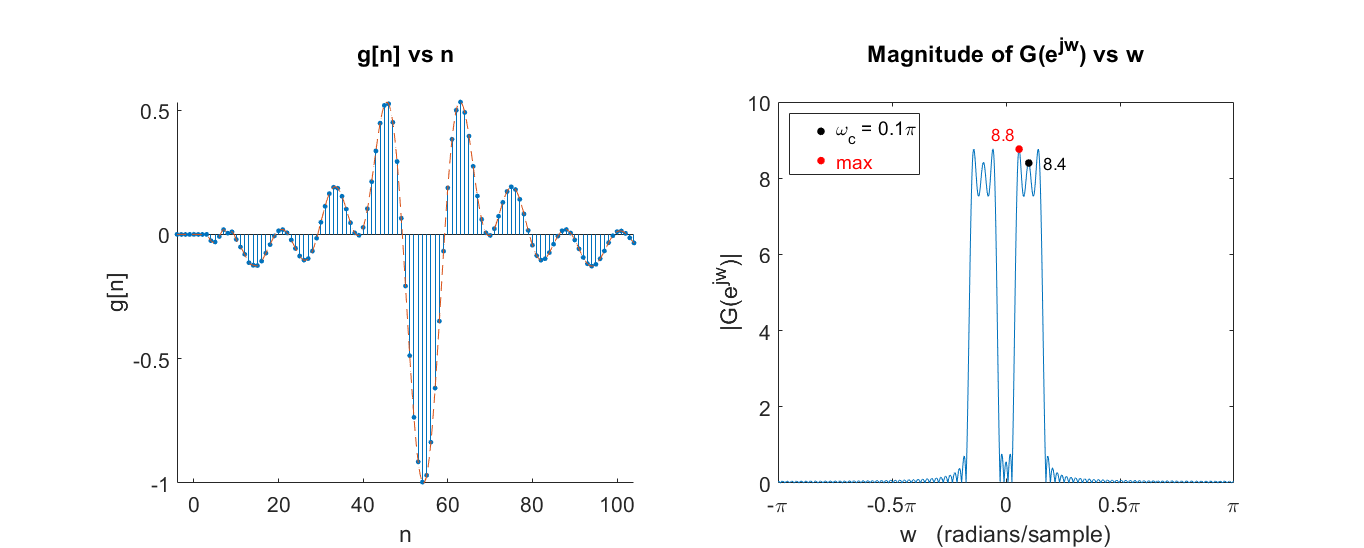

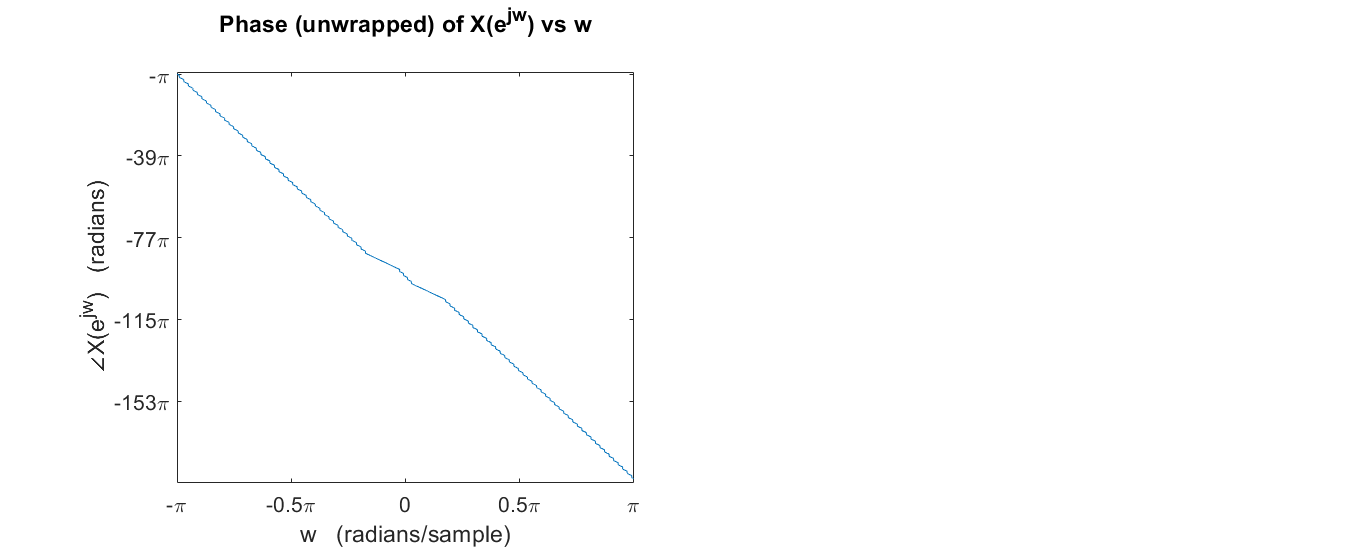

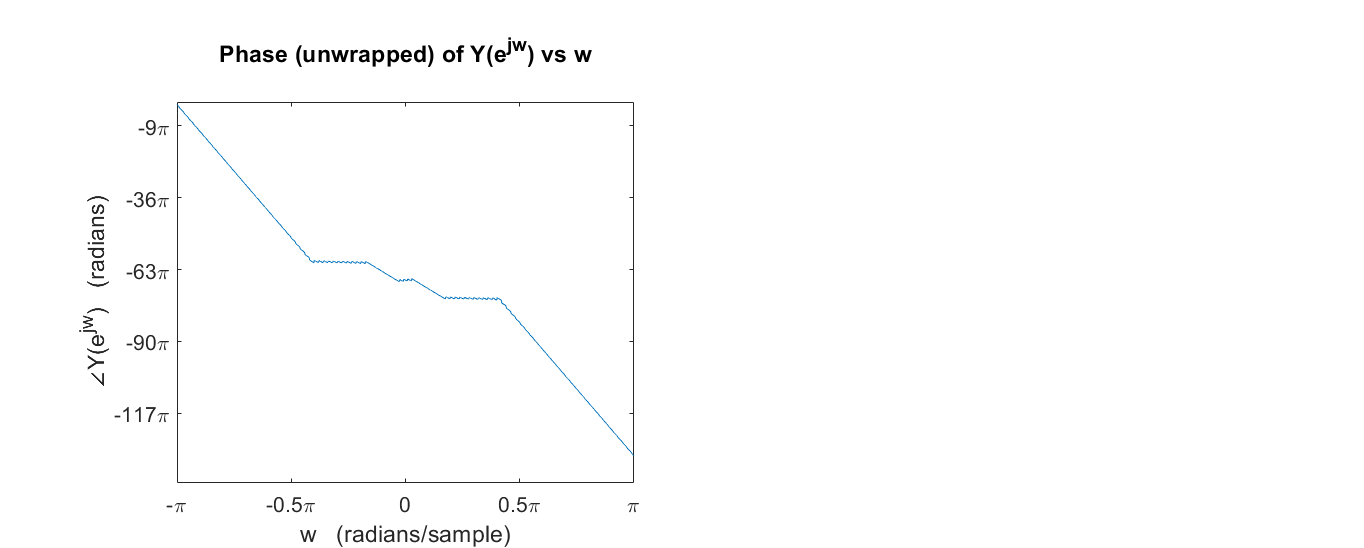

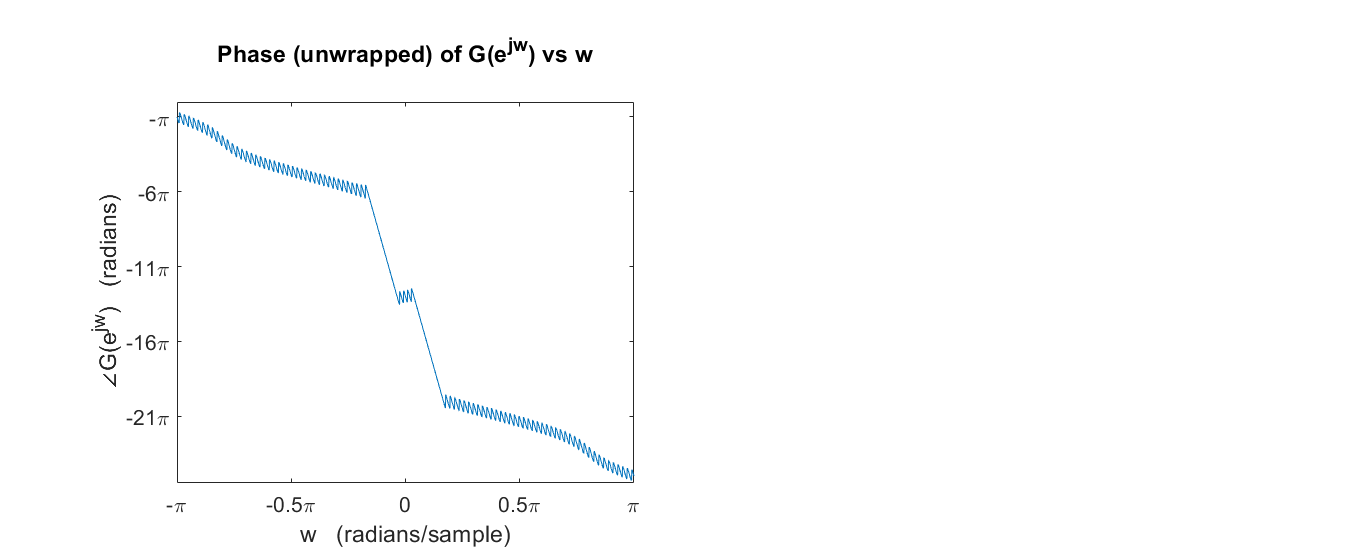

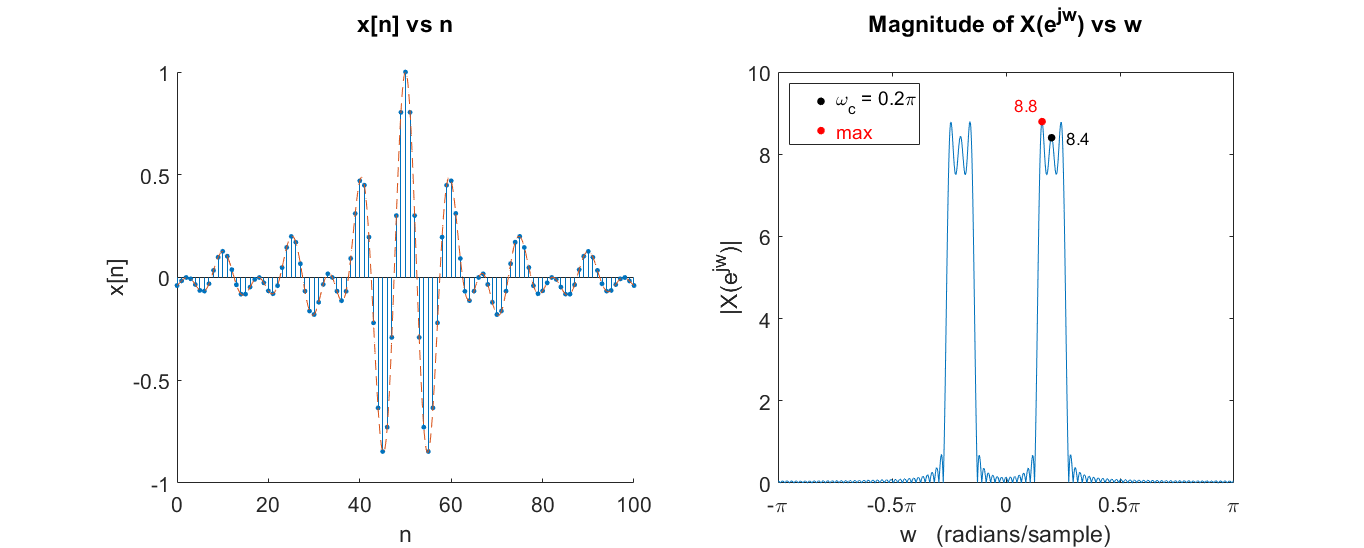

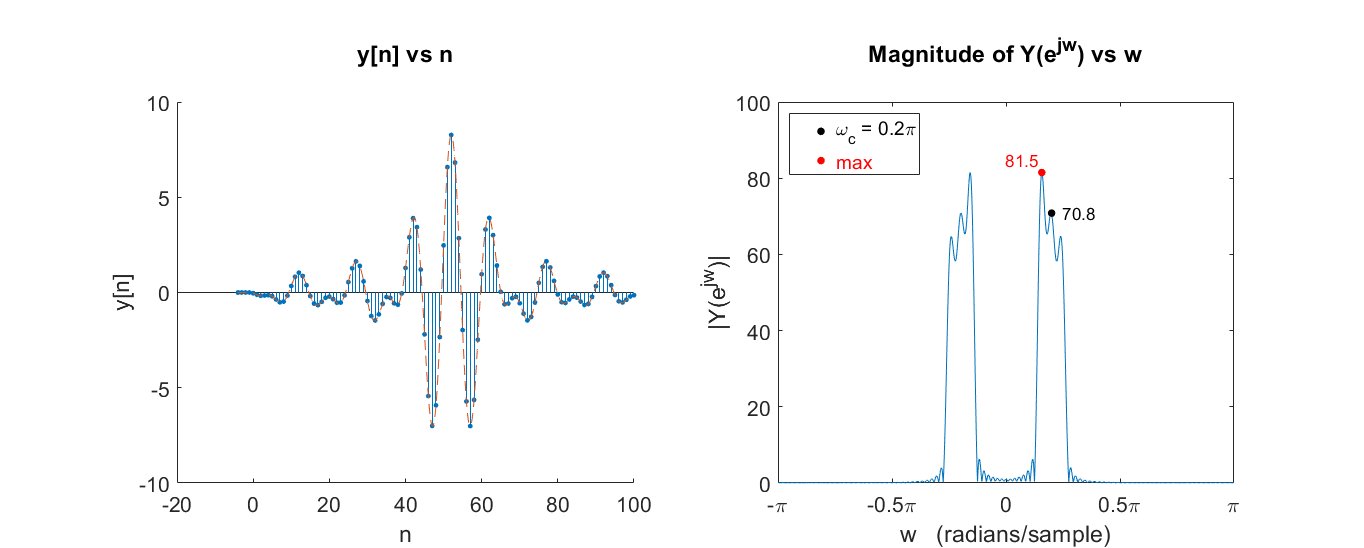

% <task> pass y[n] (for each wc value) through system Hinv(z),
% and plot the output g[n] and its spectrum

wcvals = [0.1, 0.2, 0.4, 0.8]*pi;           % wc values (x[n] center frequencies)
g = cell(1, length(wcvals));                % to store g[n] arrays for different wc
ng = cell(1, length(wcvals));               % to store ng arrays for different wc

for i = 1:length(wcvals)
    
    % assuming zero initial conditions (rest)
    N_aux = zeros(1, length(a)-1);
    M_init = zeros(1, length(b)-1);
    
    % compute output g[n], with input y[n] to system represented by Hinv(z),
    % using get_system_out() and extracted b's and a's
    [g{i}, ng{i}] = get_system_out(b, a, y{i}, N_aux, M_init);
    
    % compute DTFT G(w)
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Gw = g{i} * exp(-1i * ng{i}' * w);      % using matrix-multiplication method
    
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT G(w)
    Gw_mag = abs(Gw);
    Gw_arg = phase(Gw);
    
    % compute DTFT X(w) for comparison with G(w)
    Xw = x{i} * exp(-1i * n' * w);          % using matrix-multiplication method
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT X(w)
    Xw_mag = abs(Xw);
    Xw_arg = phase(Xw);
    
    % compute DTFT Y(w) for comparison with G(w)
    Yw = y{i} * exp(-1i * ny{i}' * w);      % using matrix-multiplication method
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT Y(w)
    Yw_mag = abs(Yw);
    Yw_arg = phase(Yw);
    
    % plot sequences x[n], y[n] & g[n], and their DTFTs' magnitudes
    plot3SeqDTFT({n, ny{i}, ng{i}}, {x{i}, y{i}, g{i}}, wcvals(i), w, ...
        {Xw_mag, Yw_mag, Gw_mag}, {'x', 'y', 'g'}, {'X', 'Y', 'G'}, ...
        {Xw_arg, Yw_arg, Gw_arg},...
        {[0.2 0 -0.04 0.4], [0.15 0 -0.04 0.04*max(Yw_mag)], [0.2 0 -0.04 0.4]}, ...
        {'left', 'right'});

end

Comparing the magnitude plots of $X\left(e^{j\omega } \right)$ and $G\left(e^{j\omega } \right)$, it can be seen that they approximately match. Hence, any magnitude distortion experienced in $Y\left(e^{j\omega } \right)$ from $H\left(z\right)$ is compensated by $H_{\textrm{inv}} \left(z\right)$. A summary of the magnitudes (maximum and at $\omega_c$) for the input and intermediate/final output of the overall system is shown below.


$$\matrix{\cr
\text{ }    	&|X(e^{j\omega})|	&|Y(e^{j\omega})| & |G(e^{j\omega})| \cr
& \text{---------------------------------} & \text{---------------------------------}& \text{---------------------------------}  \cr
\omega_c \text{\;\;\;(rad/sample)} & \matrix{\text{at }\omega_c &&&& \text{max}} &  \matrix{\text{at }\omega_c &&&& \text{max}}  &  \matrix{\text{at }\omega_c &&&& \text{max}}\cr
\text{-------------------------------} & \text{----------------------------------} & \text{---------------------------------} & \text{---------------------------------}  \cr
0.1\pi    & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{86.1 \;\;\;\;\;\;\;\;\;\;\;\; 93.4}}		& \matrix{8.4 &&&&& 8.8} 	\cr
0.2\pi    & \matrix{8.4 &&&&& 8.8}   &   \matrix{\text{70.8 \;\;\;\;\;\;\;\;\;\;\;\; 81.5}}		&  \matrix{8.4 &&&&& 8.8}  \cr
0.4\pi    & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{\;\;\;28 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\; 38}}	&  \matrix{8.4 &&&&& 8.8}  \cr
0.8\pi    & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{\;\;2.6 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 3.3}}       &  \matrix{8.3 &&&&& 8.8} \cr
}
$$



$$\matrix{
\text{ }    	&      \frac{|Y(e^{j\omega})|}{|X(e^{j\omega})|}=|H(e^{j\omega})|	    &     \frac{|G(e^{j\omega})|}{|Y(e^{j\omega})|}=|H_{inv}(e^{j\omega})|         
&         \frac{|G(e^{j\omega})|}{|X(e^{j\omega})|}=|H(e^{j\omega})||H_{inv}(e^{j\omega})|         \cr
& \text{---------------------------------} & \text{---------------------------------}& \text{------------------------------------------}  \cr
\omega_c \text{\;\;\;(rad/sample)}  & \matrix{\text{at }\omega_c &&&& \text{max}} &  \matrix{\text{at }\omega_c &&&& \text{max}}  &  \matrix{\text{at }\omega_c &&&& \text{max}}\cr
\text{-------------------------------}  & \text{----------------------------------} & \text{---------------------------------} & \text{------------------------------------------}  \cr
0.1\pi    & \matrix{\text{10.3 \;\;\;\;\;\;\;\;\;\;\;\; 10.6}}        &  \matrix{\text{0.1 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 0.1}}		& \matrix{\text{1 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\; 1}}	\cr
0.2\pi    &\matrix{\text{\;\;8.4  \;\;\;\;\;\;\;\;\;\;\;\; 9.26}}      &   \matrix{\text{0.1 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 0.1}}		& \matrix{\text{1 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\; 1}}     \cr
0.4\pi    &  \matrix{\text{\;\;3.3 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 4.3}}   &  \matrix{\text{0.3 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 0.2}}	       &  \matrix{\text{1 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\; 1}} \cr
0.8\pi    & \matrix{\text{\;\;0.3 \;\;\;\;\;\;\;\;\;\;\;\; 0.38}}      &  \matrix{\text{3.2 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 2.7}}       &  \matrix{\text{0.99 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\; 1\;\;\;\;\;}}    \cr
}
$$


The magnitude ratios for input and output of $H_{\textrm{inv}} \left(z\right)$ can be verified by noting its gains from the magnitude plot at respective center frequencies ($\omega_c$):


$$\begin{array}{l}
|H_{\textrm{inv}} \left(\;\;\;0\ldotp 1\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 1\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 1\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{10\ldotp 2}\\
|H_{\textrm{inv}} \left(\;\;\;0\ldotp 2\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 1\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 2\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{8\ldotp 3}\\
|H_{\textrm{inv}} \left(\;\;\;0\ldotp 4\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 4\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{3\ldotp 2}\\
|H_{\textrm{inv}} \left(\;\;\;0\ldotp 8\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;3\ldotp 3\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 8\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{0\ldotp 3}
\end{array}$$


These values from the magnitude plot match with the respective values of $|H_{\textrm{inv}} \left(e^{j\omega } \right)|$ computed in the table above. Hence, the following equation summarizes the magnitude variation from input to output:


$$\begin{array}{l}
|G\left(e^{j\omega } \right)|\;=\;|Y\left(e^{j\omega } \right)|\;|H_{\textrm{inv}} \left(e^{j\omega } \right)|\;=\;|X\left(e^{j\omega } \right)|\;|H\left(e^{j\omega } \right)|\;|H_{\textrm{inv}} \left(e^{j\omega } \right)|\;=\;|X\left(e^{j\omega } \right)|\;|H\left(e^{j\omega } \right)|\frac{1}{|H\left(e^{j\omega } \right)|}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;|X\left(e^{j\omega } \right)|
\end{array}$$


But the above relation is not true for the phase responses, $\angle G\left(e^{j\omega } \right)$ and $\angle X\left(e^{j\omega } \right)$, because $H_{\textrm{inv}} \left(z\right)$ does not compensate for the phase distortion (i.e. delay) introduced by $H\left(z\right)$, rather it introduces further delays in the output. This delay varies with the frequency-content of the input, and hence the output $g\left\lbrack n\right\rbrack$ does not have the same phase or exact shape as $x\left\lbrack n\right\rbrack$. This can be observed from the plots of the input and output sequences above. So, the phase plots show that,


$$\begin{array}{l}
\angle G\left(e^{j\omega } \right)\;=\;\angle Y\left(e^{j\omega } \right)+\angle H_{\textrm{inv}} \left(e^{j\omega } \right)\;=\;\angle X\left(e^{j\omega } \right)+\angle H\left(e^{j\omega } \right)+\angle H_{\textrm{inv}} \left(e^{j\omega } \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\not= \;\angle X\left(e^{j\omega } \right)
\end{array}$$


This is due to the fact that $\angle H_{\textrm{inv}} \left(e^{j\omega } \right)\not= -\angle H\left(e^{j\omega } \right)$. As a result,


$$g\left\lbrack n\right\rbrack \;\not= \;x\left\lbrack n\right\rbrack$$


Rather, $g\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \ast h\left\lbrack n\right\rbrack \ast h_{\textrm{inv}} \left\lbrack n\right\rbrack$. 

Hence, only the magnitude response of the input is recovered by using the compensator system, and not the entire input itself.

**Question (5):**

What is the magnitude, phase, group delay of the overall system, i.e., $H\left(z\right)$ cascaded with its magnitude inverse.

**Answer (5):**

We'll represent the overall cascaded system as $H_{\textrm{cas}} \left(z\right)$, given as,

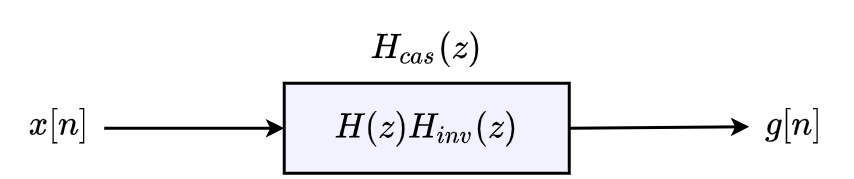

and it will have the following expression,


$$\begin{array}{l}
H_{\textrm{cas}} \left(z\right)\;=\;H\left(z\right)H_{\textrm{inv}} \left(z\right)\;=\;H\left(z\right)\frac{1}{H_{\min } \left(z\right)}\\
\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{z^4 }\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\times \frac{{\;\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)}^{-1} \;{\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)}^{-1} \;z^4 \;}{{\left(1\ldotp 25\right)}^2 \left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}\\
\\
H_{\textrm{cas}} \left(z\right)\;=\;\frac{\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{{\left(1\ldotp 25\right)}^2 \left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}
\end{array}$$


The code, along with the results (inline), to compute & plot various responses from $H_{\textrm{cas}} \left(z\right)$ expression above, starts below.

% <task> plot magnitude and phase response of cascaded system Hcas(z)

% define z-domain expression for Hcas(z) = H(z).Hinv(z)
Hcasz = Hz*Hinvz;

% display Hcas(z) expression
disp('Hcas(z) = '); disp(vpa(Hcasz, 4))

Hcas(z) = 


$$\frac{\left(z+1.011-0.7347\,\mathrm{i}\right)\,\left(z+1.011+0.7347\,\mathrm{i}\right)\,\left(z+0.2781-0.856\,\mathrm{i}\right)}{\left(1.562\,z+0.4346-1.337\,\mathrm{i}\right)\,\left(z+0.6472-0.4702\,\mathrm{i}\right)\,\left(z+0.6472+0.4702\,\mathrm{i}\right)}$$

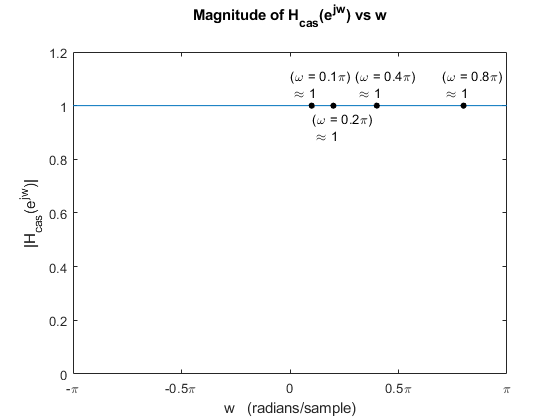


% obtain frequency response Hcas(w) expression from Hcas(z)
% by substituting z = e^(jw)
syms w_;
Hcasw = subs(Hcasz, {z}, {exp(1i*w_)});

% compute frequency response Hcas(w) for w = [-pi, pi]
dw = 0.001;
w = -pi:dw:pi;
Hcasw = subs(Hcasw, {w_}, {w});
Hcasw = double(Hcasw);

% obtain magnitude and phase of Hcas(w)
Hcasw_mag = abs(Hcasw);
Hcasw_arg = phase(Hcasw);           % unwrapped phase (in radians)
Hcasw_ARG = angle(Hcasw);           % wrapped phase (in radians)

% frequencies to be noted/marked on the response plots
wvals = [0.1, 0.2, 0.4, 0.8]*pi;

% plot magnitude of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_mag);
xlabel('w   (radians/sample)'); 
ylabel('|H_{cas}(e^{jw})|');
title({'Magnitude of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1);
markOnPlot(wvals, w, Hcasw_mag, dw, -0.1*pi, [1 -1 1 1]*0.08, ...
    {'(\omega = ', '\pi)', ''}, pi);

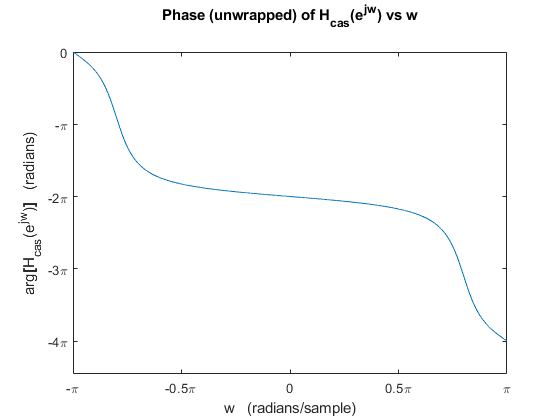


% plot phase (unwrapped) of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_arg);
xlabel('w   (radians/sample)'); 
ylabel('arg{\bf[}H_{cas}(e^{jw}){\bf]}   (radians)');
title({'Phase (unwrapped) of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 1, 1);

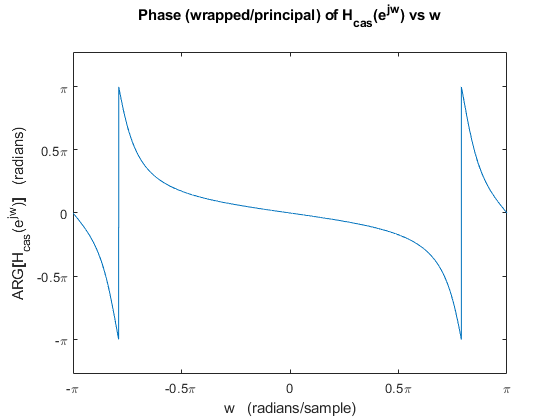


% plot phase (wrapped/principal) of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_ARG);
xlabel('w   (radians/sample)'); 
ylabel('ARG{\bf[}H_{cas}(e^{jw}){\bf]}   (radians)');
title({'Phase (wrapped/principal) of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

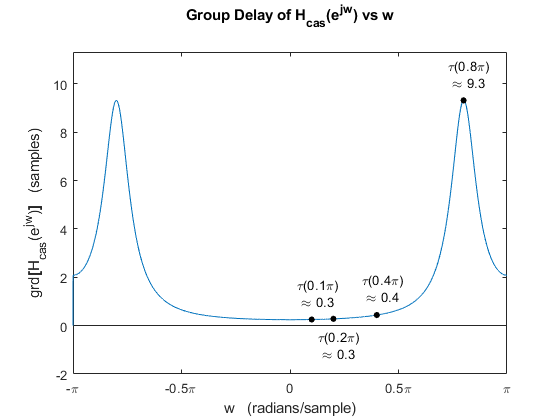


% <task> plot group-delay of cascaded system Hcas(z)

dw = (w(end)-w(1))/(length(w)-1);           % compute the w-step-size 'dw' used in w-array

% obtain group-delay of Hcas(w)
Hcasw_grd = -([Hcasw_arg 0]-[0 Hcasw_arg])/dw;
Hcasw_grd = Hcasw_grd(1:(length(Hcasw_grd)-1));

% plot group-delay of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_grd);
xlabel('w   (radians/sample)'); ylabel('grd{\bf[}H_{cas}(e^{jw}){\bf]}   (samples)');
title({'Group Delay of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1); ylim([min(Hcasw_grd)-2 max(Hcasw_grd)+2]);
markOnPlot(wvals, w, Hcasw_grd, dw, -0.07*pi, [1 -1 1 1]*1.1, {'\tau(', '\pi)', ''}, pi);


% <task> plot pole-zero map of cascaded system Hcas(z)

% extract CCDE coefficients (b's and a's) from Hcas(z) expression
[N, D] = numden(Hcasz);
b = coeffs(N, 'All');   a = coeffs(D, 'All');
b = double(b./a(1));    a = double(a./a(1));
disp('b ='); disp(b);   disp('a ='); disp(a);

b =
    0.6400    1.2944    1.0000

a =
    1.0000    1.2944    0.6400



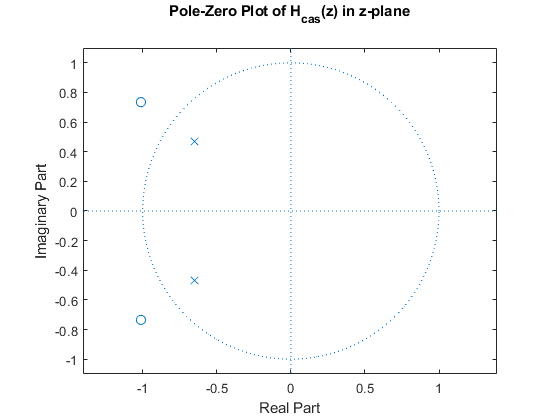


% plot the pole-zero map of Hcas(z) using extracted b's and a's
figure;
zplane(b, a);
title({'Pole-Zero Plot of H_{cas}(z) in z-plane';''});

The pole-zero map above matches with the z-domain expression $H_{\textrm{cas}} \left(z\right)$ obtained at start of this section (Q5).

The magnitude plot $|H_{\textrm{cas}} \left(e^{j\omega } \right)|$ (Page 33) shows that the gain is a constant 1 at all frequencies, that is, $H_{\textrm{cas}} \left(z\right)$ is an all-pass system. So, any input passed through the overall system experiences no magnitude distortion. Although, input will experience phase-distortion (delay in samples) affecting different frequencies differently thereby distorting the signal shape at output.

**Question (6):**

How much delay do you observe corresponding to different $\omega_c$? Can you explain the delay in the output to the group delay of the overall system $H_{\textrm{cas}} \left(z\right)$ ($H\left(z\right)$ cascaded with its inverse).

**Answer (6):**

From the group-delay plot $\tau \left(\omega \right)=\textrm{grd}\left\lbrack H_{\textrm{cas}} \left(z\right)\right\rbrack$, the delays introduced by the overall system, for specified $\omega_c$ values, can be noted as follows:


$$\begin{array}{l}
\tau \left(\;\;\;0\ldotp 1\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3\;\;\textrm{samples}\;\textrm{delay}\\
\tau \left(\;\;\;0\ldotp 2\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3\;\;\textrm{samples}\;\textrm{delay}\\
\tau \left(\;\;\;0\ldotp 4\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 4\;\;\textrm{samples}\;\textrm{delay}\\
\tau \left(\;\;\;0\ldotp 8\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;9\ldotp 3\;\;\textrm{samples}\;\textrm{delay}
\end{array}$$


Different delays occur in input for its different frequency components (due to it being a collection/pulse of frequencies). Since the frequency content in $x\left\lbrack n\right\rbrack$ (for any $\omega_c$) is banded together around $\omega_c$, we can get a rough idea of the overall delay in output $g\left\lbrack n\right\rbrack$ by looking at the delay values for its center frequency $\omega_c$ (delays noted above using the group-delay plot).

Comparing the plots of $x\left\lbrack n\right\rbrack$ and $g\left\lbrack n\right\rbrack$, for various $\omega_c$, following overall delays can be noted:


$$\begin{array}{l}
\mathrm{for}\;\;\;\omega_c =0\ldotp 1\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\;\Longrightarrow \;\;\;g\left\lbrack n\right\rbrack \;\mathrm{is}\;\mathrm{delayed}\;\mathrm{by}\;\mathrm{about}\;\;\approx \;2-3\;\;\mathrm{samples}\\
\mathrm{for}\;\;\;\omega_c =0\ldotp 2\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\;\Longrightarrow \;\;\;g\left\lbrack n\right\rbrack \;\mathrm{is}\;\mathrm{delayed}\;\mathrm{by}\;\mathrm{about}\;\;\approx \;2-3\;\;\mathrm{samples}\\
\mathrm{for}\;\;\;\omega_c =0\ldotp 4\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\;\Longrightarrow \;\;\;g\left\lbrack n\right\rbrack \;\mathrm{is}\;\mathrm{delayed}\;\mathrm{by}\;\mathrm{about}\;\;\approx \;3-4\;\;\mathrm{samples}\\
\mathrm{for}\;\;\;\omega_c =0\ldotp 8\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\;\Longrightarrow \;\;\;g\left\lbrack n\right\rbrack \;\mathrm{is}\;\mathrm{delayed}\;\mathrm{by}\;\mathrm{about}\;\;\approx \;10\;\;\mathrm{samples}
\end{array}$$


compared to $x\left\lbrack n\right\rbrack$. 

This agrees with the group-delays noted for the center-frequencies $\omega_c =0\ldotp 1\pi ,\;0\ldotp 2\pi ,\;0\ldotp 4\pi ,\;0\ldotp 8\pi$ $\textrm{rad}/\textrm{sample}$ above, that is, input with frequencies around $0\ldotp 1\pi ,\;0\ldotp 2\pi ,\;04\ldotp \pi \;\textrm{rad}/\textrm{sample}$ incurs a small delay (2 or 3 samples), while input with frequencies around $0\ldotp 8\pi \;\textrm{rad}/\textrm{sample}$ incurs a larger delay ($\approx 10\;\textrm{samples}$).

*Functions used in the tasks are provided starting on the next page.*

## Functions used in the tasks

### markOnPlot()

Used in Task 1 (Q1, Q4.a, Q5) — to mark given x-axis datapoints on given plot curve.

% <function> 
% marks given dat(x) values on plot.
%
% <syntax>
% markOnPlot(xvals, x, dat, tol, xoff, yoff, <txt>, <xdiv>, <rnd>)
%
% <I/O>
% xvals, x, dat = values on x-axis to mark, x-axis array, y-axis dat(x) array
% tol = tolerance in finding x-value in x-axis array
% xoff, yoff = horizontal, vertical offset of text (value/array)
% txt = cell structure specifying text to show around values

function markOnPlot(xvals, x, dat, tol, xoff, yoff, txt, xdiv, rnd)

    if length(xoff)==1; xoff = repelem(xoff, length(xvals));
    elseif isempty(xoff); xoff = repelem(0, length(xvals)); end
    if length(yoff)==1; yoff = repelem(yoff, length(xvals));
    elseif isempty(yoff); yoff = repelem(0, length(xvals)); end
    txt1 = 'y('; txt2 = ')'; txt_eq = '\approx'; newline = 0;
    if nargin >= 7
        txt1 = txt{1}; txt2 = txt{2};
        if length(txt) >= 3
            if isequal(txt{3}, ''); newline = 1; else; txt_eq = txt{2}; end
        end
    end
    if ~(nargin >= 8); xdiv = 1; end; if ~(nargin == 9); rnd = 1; end
    
    hold on;
    for i = 1:length(xvals)
        yval = dat(find(x>=xvals(i)-tol & x<=xvals(i)+tol, 1));
        stem(xvals(i), yval, 'k', 'filled', 'LineStyle', 'none', 'MarkerSize', 4);
        if newline
          text(xvals(i)+xoff(i), yval+yoff(i), {[txt1, num2str(xvals(i)/xdiv), txt2]; ...
            [' ', txt_eq,' ', num2str(round(yval, rnd))]});          
        else
            text(xvals(i)+xoff(i), yval+yoff(i), [txt1, num2str(xvals(i)/xdiv), txt2, ...
                ' ', txt_eq,' ', num2str(round(yval, rnd))]);
        end
    end
    hold off;
    
end

### plot2SeqDTFT()

Used in Task 1 (Q3) — to plot 2 sequences and their DTFTs (magnitude and unwrapped-phase response).

% <function> 
% plots given sequence(s) against given n values and their given DTFT 
% (magnitude and phase response) against given w values.
%
% <syntax>
% plot2SeqDTFT(n, x, wc, w, Xw_mag, Xw_arg, Nn, Nw, off, ...
%     <ny>, <y>, <Yw_mag>, <Yw_arg>, <Nny>, <Nwy>, <align1>, <align2>);
%
% <I/O>
% x = sequence x[n] array
% wc = center frequency of x[n]
% w = DT frequencies array [-pi, pi]
% Xw_mag, Xw_arg = DTFT magnitude, phase (unwrapped)
% Nn = name of sequence x[n] for label/title in plot
% Nw = name of DTFT X(w) for label/title in plot
% off = offsets for texts in form of array
% y = optional sequence y[n] array
% Yw_mag, Yw_arg = optional y[n] DTFT magnitude, phase (unwrapped)
% Nny = name of optional sequence y[n] for label/title in plot
% Nwy = name of optional y[n] DTFT for label/title in plot

function plot2SeqDTFT(n, x, wc, w, Xw_mag, Xw_arg, Nn, Nw, off, ...
    ny, y, Yw_mag, Yw_arg, Nny, Nwy, align1, align2);
    
    if length(off) < 4; off = [off repelem(0, 4-length(off))]; end 
    plt2 = 0;
    if nargin >= 10
        plt2 = 1;
        if length(off) < 8; off = [off repelem(0, 8-length(off))]; end
    end
    if ~(nargin >= 16); align1 = 'left'; end; if ~(nargin == 17); align2 = 'left'; end
    lb2 = round(length(w)/2); w2 = w(lb2:end);

    % plot sequence(s)
    fig = figure;
    if plt2
        set(fig,'Units','normalized','Position',[0 0 1.4 1]);
        subplot(1, 2, 1);
    end
        % plot x[n] vs n
        hold on;
            stem(n, x, 'filled', 'MarkerSize', 3);
            n2 = min(n):1/1000:max(n);
            plot(n2, interp1(n,x,n2,'spline'), '--');
        hold off;
        xlabel('n'); ylabel([Nn, '[n]']);
        if plt2
            title({['{\bf', Nn, '[n] vs n}'];''}, 'FontSize', 16);
            ax = gca; ax.FontSize = 16;
        else
            title({'';['{\bf', Nn, '[n] vs n}'];''});
        end
    if plt2
        subplot(1, 2, 2);
        % plot y[n] vs n
        hold on;
            stem(ny, y, 'filled', 'MarkerSize', 3);
            n2 = min(ny):1/1000:max(ny);
            plot(n2, interp1(ny,y,n2,'spline'), '--');
        hold off;
        xlabel('n'); ylabel([Nny, '[n]']);
        xlim([min(n) max(n)]);
        title({['{\bf', Nny, '[n] vs n}'];''}, 'FontSize', 16);
        ax = gca; ax.FontSize = 16;
    end
        
    % plot magnitude and phase of DTFT X(w) vs w
    fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 1]);
    subplot(1, 2, 1);
    plot(w, Xw_mag);
    xlabel('w   (radians/sample)'); ylabel(['|', Nw, '(e^{jw})|']);
    title({'';['{\bfMagnitude of ', Nw, '(e^{jw}) vs w}'];''}, 'FontSize', 16);
    setDTFTradialAxis(1); 
    ax = gca; ax.FontSize = 16;
    hold on;
        yval = Xw_mag(find(w>=wc-0.01 & w<=wc+0.01, 1));
        l1 = stem(wc, yval, 'k', 'filled', 'LineStyle', 'none', 'MarkerSize', 5);
        text(wc+off(1), yval+off(2), num2str(round(yval, 1)), ...
            'FontSize', 13, 'HorizontalAlignment', align1);
        [yval, yinx] = max(Xw_mag(lb2:end)); wval = w2(yinx);
        l2 = stem(wval, yval, 'r', 'filled', 'LineStyle', 'none', 'MarkerSize', 5);
        text(wval+off(3), yval+off(4), num2str(round(yval, 1)), ...
            'Color', 'r', 'FontSize', 13, 'HorizontalAlignment', align2);
        legend([l1 l2], ['\omega_c = ', num2str(wc/pi), '\pi'], ...
            '{\color{red}max}', 'Location', 'northwest');
    hold off;
    subplot(1, 2, 2);
    plot(w, Xw_arg);
    xlabel('w   (radians/sample)'); ylabel(['∠', Nw, '(e^{jw})   (radians)']);
    title({'';['{\bfPhase (unwrapped) of ', Nw, '(e^{jw}) vs w}'];''}, ...
        'FontSize', 16);
    step = round(max(abs([max(Xw_arg) min(Xw_arg)]))/pi*0.2);
    setDTFTradialAxis(1, step, 1);
    ax = gca; ax.FontSize = 16;

    if plt2
        % plot magnitude and phase of DTFT Y(w) vs w
        fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 1]);
        subplot(1, 2, 1);
        plot(w, Yw_mag);
        xlabel('w   (radians/sample)'); ylabel(['|', Nwy, '(e^{jw})|']);
        title({'';['{\bfMagnitude of ', Nwy, '(e^{jw}) vs w}'];''}, 'FontSize', 16);
        setDTFTradialAxis(1); 
        ax = gca; ax.FontSize = 16;
        hold on;
            yval = Yw_mag(find(w>=wc-0.01 & w<=wc+0.01, 1));
            l1 = stem(wc, yval, 'k', 'filled', 'LineStyle', 'none', 'MarkerSize', 5);
            text(wc+off(5), yval+off(6), num2str(round(yval, 1)), ...
                'FontSize', 13, 'HorizontalAlignment', align1);     
            [yval, yinx] = max(Yw_mag(lb2:end)); wval = w2(yinx);
            l2 = stem(wval, yval, 'r', 'filled', 'LineStyle', 'none', 'MarkerSize', 5);
            text(wval+off(7), yval+off(8), num2str(round(yval, 1)), ...
                'Color', 'r', 'FontSize', 13, 'HorizontalAlignment', align2);
            legend([l1 l2], ['\omega_c = ', num2str(wc/pi), '\pi'], ...
                '{\color{red}max}', 'Location', 'northwest');
        hold off;
        subplot(1, 2, 2);
        plot(w, Yw_arg);
        xlabel('w   (radians/sample)'); ylabel(['∠', Nwy, '(e^{jw})   (radians)']);
        title({'';['{\bfPhase (unwrapped) of ', Nwy, '(e^{jw}) vs w}'];''}, ...
            'FontSize', 16);
        step = round(max(abs([max(Yw_arg) min(Yw_arg)]))/pi*0.2);
        setDTFTradialAxis(1, step, 1);
        ax = gca; ax.FontSize = 16;
    end

end

### plot3SeqDTFT()

Used in Task 1 (Q4.b) — to plot 3 sequences and their DTFTs (magnitude and unwrapped-phase response).

% <function> 
% plots given sequence(s) against given n values and their given DTFT 
% (magnitude and phase response) against given w values.
%
% <syntax>
% plot3SeqDTFT(n, a, wc, w, Aw_mag, Nn, Nw, Aw_arg, <off>, <align>)
%
% <I/O>
% a = {x[n], y[n], g[n]}
% wc = center frequency of a[n]
% w = DT frequencies array [-pi, pi]
% Aw_mag = {Xw_mag, Yw_mag, Gw_mag}
% Nn = {Nnx, Nny, Nng}
% Nw = {Nwx, Nwy, Nwg}
% Aw_arg = optional {Xw_arg, Yw_arg, Gw_arg}
% off = optional {offX, offY, offG}
% align = optional {alignWC, alignMX}

function plot3SeqDTFT(n, a, wc, w, Aw_mag, Nn, Nw, Aw_arg, off, align)
    
    if ~(nargin >= 8); Aw_arg = {}; end
    if ~(nargin >= 9); off = {zeros(1, 4), zeros(1, 4), zeros(1, 4)}; end
    if ~(nargin == 10); align = {'left', 'left'}; end
    lb2 = round(length(w)/2); w2 = w(lb2:end);
    
    for i = 1:length(n)
        % plot sequence a[n] and DTFT A(w) magnitude
        fig = figure;
        set(fig,'Units','normalized','Position',[0 0 1.4 1]);
        subplot(1, 2, 1);
        % plot a[n] vs n
        hold on;
            stem(n{i}, a{i}, 'filled', 'MarkerSize', 3);
            n2 = min(n{i}):1/1000:max(n{i});
            plot(n2, interp1(n{i},a{i},n2,'spline'), '--');
        hold off;
        xlabel('n'); 
        ylabel([Nn{i}, '[n]']);
        if (i == 1)
            title({['{\bf', Nn{i}, '[n] vs n}'];''}, 'FontSize', 16);
        else
            title({'';['{\bf', Nn{i}, '[n] vs n}'];''}, 'FontSize', 16);
        end
        ax = gca; ax.FontSize = 16;
        subplot(1, 2, 2);
        % plot magnitude of A(w) vs w
        plot(w, Aw_mag{i});
        xlabel('w   (radians/sample)'); 
        ylabel(['|', Nw{i}, '(e^{jw})|']);
        if (i == 1)
            title({['{\bfMagnitude of ', Nw{i}, '(e^{jw}) vs w}'];''}, 'FontSize', 16);
        else
            title({'';['{\bfMagnitude of ', Nw{i}, '(e^{jw}) vs w}'];''}, ...
                'FontSize', 16);
        end
        setDTFTradialAxis(1); 
        ax = gca; ax.FontSize = 16;
        % mark wc and max points on plot
        hold on;
            yval = Aw_mag{i}(find(w>=wc-0.01 & w<=wc+0.01, 1));
            l1 = stem(wc, yval, 'k', 'filled', 'LineStyle', 'none', 'MarkerSize', 5);
            text(wc+off{i}(1), yval+off{i}(2), num2str(round(yval, 1)), ...
                'FontSize', 13, 'HorizontalAlignment', align{1});
            [yval, yinx] = max(Aw_mag{i}(lb2:end)); wval = w2(yinx);
            l2 = stem(wval, yval, 'r', 'filled', 'LineStyle', 'none', 'MarkerSize', 5);
            text(wval+off{i}(3), yval+off{i}(4), num2str(round(yval, 1)), ...
                'Color', 'r', 'FontSize', 13, 'HorizontalAlignment', align{2});
            legend([l1 l2], ['\omega_c = ', num2str(wc/pi), '\pi'], ...
                '{\color{red}max}', 'Location', 'northwest');
        hold off;
    end
    
    for i = 1:length(Aw_arg)
        % plot DTFT A(w) phase (unwrapped)
        fig = figure;
        set(fig,'Units','normalized','Position',[0 0 1.4 1]);
        subplot(1, 2, 1)
        plot(w, Aw_arg{i});
        xlabel('w   (radians/sample)'); 
        ylabel(['∠', Nw{i}, '(e^{jw})   (radians)']);
        if (i == 1)
            title({['{\bfPhase (unwrapped) of ', Nw{i}, '(e^{jw}) vs w}'];''}, ...
                'FontSize', 16);
        else
            title({'';['{\bfPhase (unwrapped) of ', Nw{i}, '(e^{jw}) vs w}'];''}, ...
                'FontSize', 16);
        end
        step = round(max(abs([max(Aw_arg{i}) min(Aw_arg{i})]))/pi*0.2);
        setDTFTradialAxis(1, step, 1);
        ax = gca; ax.FontSize = 16;
    end
    
end

'End of Report';